# Part 1

clear
close all

x = sym( "x", "real" );
target_fun = sin( pi * x ) ^ 2;
domain = [-1, 1];
degree = 8;
basis_family = "Monomial";

[u, M, F, N, d] = ScalarProjection( basis_family, target_fun, degree, domain )

$$u(x) = \frac{2162160\,\pi^{4}-18918900\,\pi^{2}-63360\,\pi^{6}+256\,\pi^{8}+34459425}{512\,\pi^{8}}+\frac{984555\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{7}\,\left(120120\,\pi^{2}-12320\,\pi^{4}+256\,\pi^{6}-225225\right)}{64\,\pi^{8}}-\frac{984555\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{8}\,\left(120120\,\pi^{2}-12320\,\pi^{4}+256\,\pi^{6}-225225\right)}{256\,\pi^{8}}-\frac{1576575\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{4}\,\left(202500\,\pi^{2}-20976\,\pi^{4}+448\,\pi^{6}-378675\right)}{256\,\pi^{8}}+\frac{45045\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{3}\,\left(473760\,\pi^{2}-49560\,\pi^{4}+1088\,\pi^{6}-883575\right)}{64\,\pi^{8}}-\frac{10395\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{2}\,\left(562380\,\pi^{2}-59800\,\pi^{4}+1376\,\pi^{6}-1044225\right)}{128\,\pi^{8}}-\frac{315315\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{6}\,\left(1225620\,\pi^{2}-125856\,\pi^{4}+2624\,\pi^{6}-2297295\right)}{128\,\pi^{8}}+\frac{135135\,{\left(\frac{x}{2}+\frac{1}{2}\right)}^{5}\,\left(1226610\,\pi^{2}-126336\,\pi^{4}+2656\,\pi^{6}-2297295\right)}{64\,\pi^{8}}+\frac{495\,\left(\frac{x}{2}+\frac{1}{2}\right)\,\left(339885\,\pi^{2}-37128\,\pi^{4}+928\,\pi^{6}-626535\right)}{64\,\pi^{8}}$$

$$M = \left[\begin{array}{ccccccccc} 2 & 1 & \frac{2}{3} & \frac{1}{2} & \frac{2}{5} & \frac{1}{3} & \frac{2}{7} & \frac{1}{4} & \frac{2}{9}\\ 1 & \frac{2}{3} & \frac{1}{2} & \frac{2}{5} & \frac{1}{3} & \frac{2}{7} & \frac{1}{4} & \frac{2}{9} & \frac{1}{5}\\ \frac{2}{3} & \frac{1}{2} & \frac{2}{5} & \frac{1}{3} & \frac{2}{7} & \frac{1}{4} & \frac{2}{9} & \frac{1}{5} & \frac{2}{11}\\ \frac{1}{2} & \frac{2}{5} & \frac{1}{3} & \frac{2}{7} & \frac{1}{4} & \frac{2}{9} & \frac{1}{5} & \frac{2}{11} & \frac{1}{6}\\ \frac{2}{5} & \frac{1}{3} & \frac{2}{7} & \frac{1}{4} & \frac{2}{9} & \frac{1}{5} & \frac{2}{11} & \frac{1}{6} & \frac{2}{13}\\ \frac{1}{3} & \frac{2}{7} & \frac{1}{4} & \frac{2}{9} & \frac{1}{5} & \frac{2}{11} & \frac{1}{6} & \frac{2}{13} & \frac{1}{7}\\ \frac{2}{7} & \frac{1}{4} & \frac{2}{9} & \frac{1}{5} & \frac{2}{11} & \frac{1}{6} & \frac{2}{13} & \frac{1}{7} & \frac{2}{15}\\ \frac{1}{4} & \frac{2}{9} & \frac{1}{5} & \frac{2}{11} & \frac{1}{6} & \frac{2}{13} & \frac{1}{7} & \frac{2}{15} & \frac{1}{8}\\ \frac{2}{9} & \frac{1}{5} & \frac{2}{11} & \frac{1}{6} & \frac{2}{13} & \frac{1}{7} & \frac{2}{15} & \frac{1}{8} & \frac{2}{17} \end{array}\right]$$

$$F = \left[\begin{array}{c} 1\\ \frac{1}{2}\\ \frac{1}{3}-\frac{1}{8\,\pi^{2}}\\ \frac{1}{4}-\frac{3}{16\,\pi^{2}}\\ \frac{1}{5}-\frac{\frac{\pi^{2}}{4}-\frac{3}{32}}{\pi^{4}}\\ \frac{1}{6}-\frac{\frac{5\,\pi^{2}}{16}-\frac{15}{64}}{\pi^{4}}\\ \frac{1}{7}-\frac{\frac{3\,\pi^{4}}{8}-\frac{15\,\pi^{2}}{32}+\frac{45}{256}}{\pi^{6}}\\ \frac{1}{8}-\frac{\frac{7\,\pi^{4}}{16}-\frac{105\,\pi^{2}}{128}+\frac{315}{512}}{\pi^{6}}\\ \frac{1}{9}-\frac{\frac{105\,\pi^{2}}{64}-\frac{21\,\pi^{4}}{16}+\frac{\pi^{6}}{2}-\frac{315}{512}}{\pi^{8}} \end{array}\right]$$

$$N = \left[\begin{array}{c} 1\\ \frac{x}{2}+\frac{1}{2}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{2}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{3}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{4}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{5}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{6}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{7}\\ {\left(\frac{x}{2}+\frac{1}{2}\right)}^{8} \end{array}\right]$$

$$d = \left[\begin{array}{c} \frac{2162160\,\pi^{4}-18918900\,\pi^{2}-63360\,\pi^{6}+256\,\pi^{8}+34459425}{512\,\pi^{8}}\\ \frac{495\,\left(339885\,\pi^{2}-37128\,\pi^{4}+928\,\pi^{6}-626535\right)}{64\,\pi^{8}}\\ -\frac{10395\,\left(562380\,\pi^{2}-59800\,\pi^{4}+1376\,\pi^{6}-1044225\right)}{128\,\pi^{8}}\\ \frac{45045\,\left(473760\,\pi^{2}-49560\,\pi^{4}+1088\,\pi^{6}-883575\right)}{64\,\pi^{8}}\\ -\frac{1576575\,\left(202500\,\pi^{2}-20976\,\pi^{4}+448\,\pi^{6}-378675\right)}{256\,\pi^{8}}\\ \frac{135135\,\left(1226610\,\pi^{2}-126336\,\pi^{4}+2656\,\pi^{6}-2297295\right)}{64\,\pi^{8}}\\ -\frac{315315\,\left(1225620\,\pi^{2}-125856\,\pi^{4}+2624\,\pi^{6}-2297295\right)}{128\,\pi^{8}}\\ \frac{984555\,\left(120120\,\pi^{2}-12320\,\pi^{4}+256\,\pi^{6}-225225\right)}{64\,\pi^{8}}\\ -\frac{984555\,\left(120120\,\pi^{2}-12320\,\pi^{4}+256\,\pi^{6}-225225\right)}{256\,\pi^{8}} \end{array}\right]$$

l2_error = ComputeL2Error( target_fun, u, domain )

$$l2\_error = \sqrt{\frac{1}{4}-\frac{\frac{1720792198125\,\pi^{4}}{8192}-\frac{4656674397375\,\pi^{2}}{8192}-\frac{8312829525\,\pi^{6}}{256}+\frac{1173647475\,\pi^{8}}{512}-\frac{2297295\,\pi^{10}}{32}+\frac{14355\,\pi^{12}}{16}+\frac{69850115960625}{131072}}{\pi^{16}}}$$

l2_error = vpa( l2_error )

$$l2\_error = 0.0093106559094715150015774869930669$$

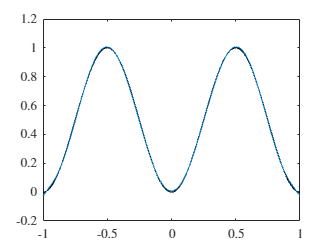


figure
hold on
fplot( target_fun, domain, color="k" )
fplot( u, domain, SeriesIndex=1 )

## Part 2

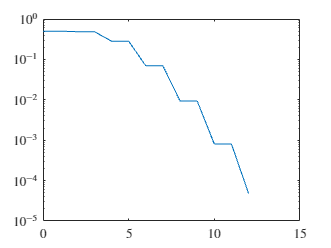

clear
close all

x = sym( "x", "real" );
target_fun = sin( pi * x ) ^ 2;
domain = [-1, 1];
basis_family = "Monomial";

degree = (0:12);
l2_error = zeros( size( degree ) );
for p = 1 : length( degree )
    u = ScalarProjection( basis_family, target_fun, degree(p), domain );
    l2_error(p) = double( vpa( ComputeL2Error( target_fun, u, domain ), 16 ) );
end

figure
semilogy( degree, l2_error )